clc
clear all
close all
order=4

order = 4

fc=0.2

fc = 0.2000

[b,a]=butter(order,fc,'low')

b =     0.0048    0.0193    0.0289    0.0193    0.0048


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


disp(b)

    0.0048    0.0193    0.0289    0.0193    0.0048



disp(a)

    1.0000   -2.3695    2.3140   -1.0547    0.1874



freqz(b,a,12400,'half',44100)
sgnl=randn(1,1000)

sgnl =     0.6737   -0.6691   -0.4003   -0.6718    0.5756   -0.7781   -1.0636    0.5530   -0.4234    0.3616   -0.3519    0.2695   -2.5644    0.4659    1.8536    1.0393    0.9109   -0.2397    0.1810    0.2442    0.0964   -0.8305   -0.3523   -0.1748   -0.4807    0.8368    2.5383   -1.3233    0.1283   -1.4424    1.3025    1.4099   -1.6625    1.9437   -1.0847    0.2268    1.0989    0.1472    2.2957    2.7526    0.1383   -1.9071   -0.3650   -0.8481   -0.7648   -1.1277    0.0782    2.1066   -0.7158   -0.2805


filsgnl=filter(b,a,sgnl)

filsgnl =     0.0033    0.0175    0.0385    0.0370   -0.0152   -0.1072   -0.2055   -0.2943   -0.3665   -0.3987   -0.3700   -0.2860   -0.1858   -0.1385   -0.1832   -0.2500   -0.2050    0.0101    0.3205    0.5870    0.7086    0.6640    0.4835    0.2177   -0.0667   -0.2976   -0.4023   -0.3190   -0.0641    0.2282    0.3967    0.3904    0.2895    0.1945    0.1460    0.1392    0.1507    0.1693    0.2169    0.3391    0.5804    0.9056    1.1496    1.1265    0.7888    0.2441   -0.3359   -0.7797   -0.9466   -0.7969


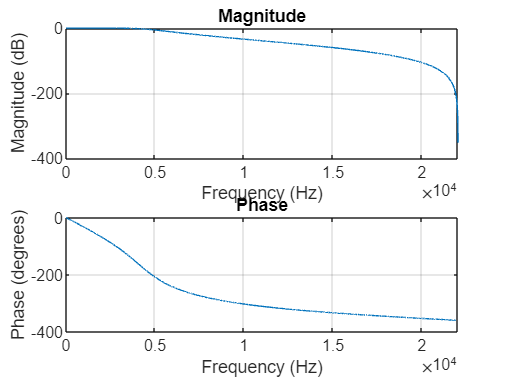

subplot(2,1,1)

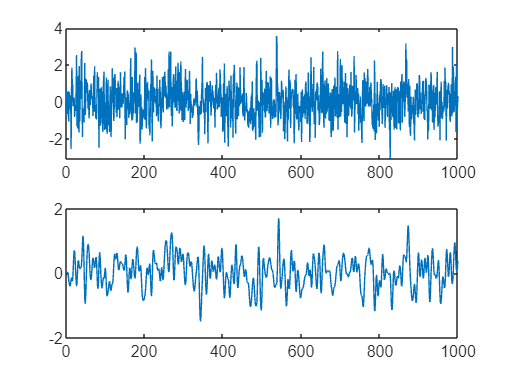

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
fc=0.2

fc = 0.2000

order=4

order = 4

[b,a]=butter(order,fc,"high")

b =     0.4328   -1.7314    2.5971   -1.7314    0.4328


a =     1.0000   -2.3695    2.3140   -1.0547    0.1874


freqz(b,a,12400,'half',44100)
sgnl=randn(1,1000)

sgnl =     0.2962    1.2008    1.0902   -0.3587   -0.1299    0.7337    0.1203    1.1363   -0.6868    0.4717    0.2883    1.3919   -1.3455    0.0007    0.0535   -2.3419    1.2481    2.8092   -0.2322    0.2870   -0.4646    0.3843   -0.3798   -0.1018    1.6182   -0.8472   -0.5759   -0.0759   -0.1325    1.4393    2.0313   -0.9782   -0.6410    0.5205   -0.3807    1.9929    1.6359    0.5590    0.5636   -0.3384    0.7636    1.1274    0.1416    1.9281    0.6706   -0.1101    0.3710    1.0966   -0.3982   -0.0855


filsgnl=filter(b,a,sgnl)

filsgnl =     0.1282    0.3107   -0.3983   -0.9647    0.3848    0.9090   -0.1421    0.4052   -1.1033    0.5816   -0.0057    0.4102   -1.5519    0.9081    0.4189   -0.9945    2.0728    0.3651   -2.7037   -0.2315    0.0798    1.1390    0.1429    0.3707    0.7578   -1.7337   -0.0654    0.5048    0.1226    0.6640   -0.2404   -2.0772    0.4538    1.4048   -0.0250    1.1178   -0.8066   -1.3177   -0.1629   -0.0372    1.1706    0.4880   -0.6387    0.6478   -0.9937   -0.5770    0.5510    0.6911   -0.6863    0.2742


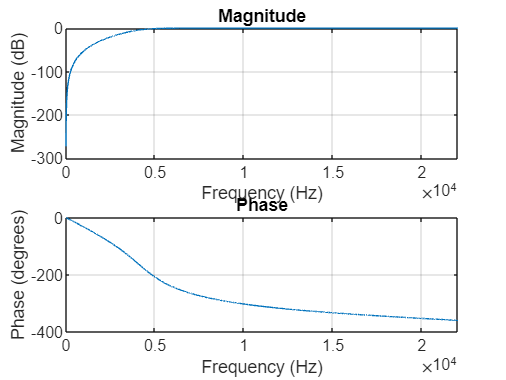

subplot(2,1,1)

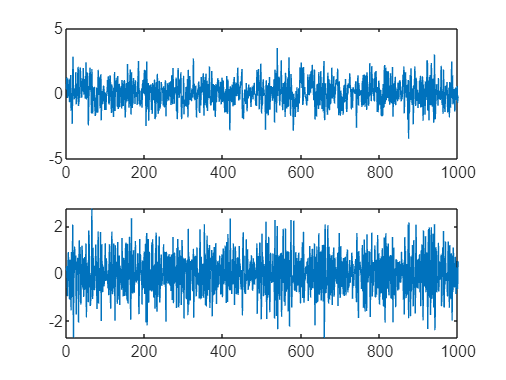

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
fl=0.1

fl = 0.1000

fh=0.2

fh = 0.2000

order=4

order = 4

[b,a]=butter(order,[fl fh],'bandpass')

b =     0.0004         0   -0.0017         0    0.0025         0   -0.0017         0    0.0004


a =     1.0000   -6.4777   18.9710  -32.7361   36.3673  -26.6260   12.5511   -3.4869    0.4383


freqz(b,a,2400,'half',44100)
sgnl=randn(1,1000)

sgnl =     0.8706    0.3308   -1.3479    1.5479   -0.6166   -0.6986   -1.4236   -0.1096   -0.1027   -0.3227   -0.8396   -1.6606    3.0125    1.5008   -0.3590   -0.1149    0.3589   -0.0121   -0.5704    0.9340   -1.1383    1.9572   -1.7632   -0.3233    0.8726    0.1179   -1.5031    0.9218    0.1632   -0.8147    0.4037    0.7562    2.1844   -0.0938   -0.2942   -0.5048   -1.9270    0.5214   -2.0544   -0.2698   -0.2750    0.8451   -2.7712    0.9181   -0.5193   -1.2930   -0.0087    0.2334   -0.4242   -1.4694


filsgnl=filter(b,a,sgnl)

filsgnl =     0.0004    0.0025    0.0072    0.0115    0.0102    0.0007   -0.0167   -0.0401   -0.0629   -0.0715   -0.0520   -0.0011    0.0688    0.1389    0.1932    0.2151    0.1838    0.0850   -0.0732   -0.2555   -0.4073   -0.4725   -0.4148   -0.2357    0.0217    0.2879    0.4921    0.5812    0.5339    0.3678    0.1319   -0.1116   -0.3033   -0.4010   -0.3939   -0.3083   -0.1957   -0.1071   -0.0675   -0.0657   -0.0645   -0.0210    0.0896    0.2540    0.4215    0.5264    0.5151    0.3686    0.1133   -0.1862


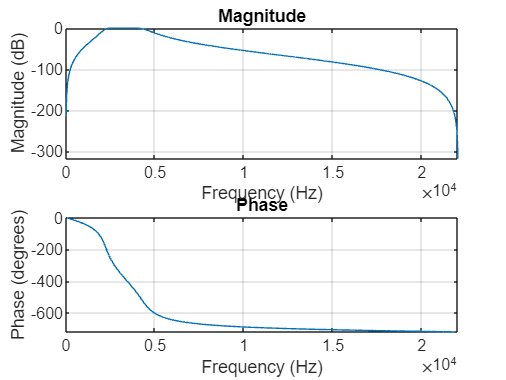

subplot(2,1,1)

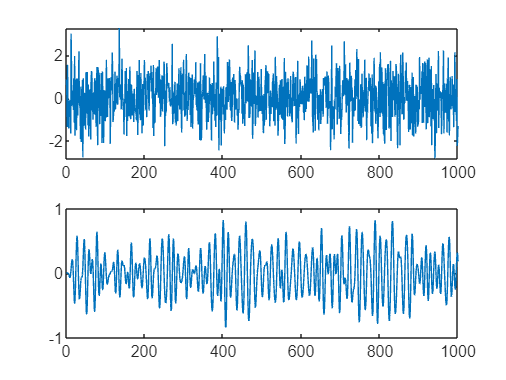

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
fl=0.1

fl = 0.1000

fh=0.2

fh = 0.2000

order=4

order = 4

[b,a]=butter(order,[fl fh],"stop")

b =     0.6620   -4.7777   15.5782  -29.8857   36.8473  -29.8857   15.5782   -4.7777    0.6620


a =     1.0000   -6.4777   18.9710  -32.7361   36.3673  -26.6260   12.5511   -3.4869    0.4383


freqz(b,a,2400,'half',44100)
sgnl=randn(1,1000)

sgnl =    -0.4277   -0.5794    0.9260    0.0055   -0.6345    0.8583   -0.4808    1.4897   -0.6294   -0.5940   -0.6287    0.3563    1.3051    0.3657    0.7721    1.2553   -0.1283    0.9486   -0.1245    2.0999    0.2603   -0.5455    0.1004   -0.7329   -1.5242    0.3498    0.2329    0.6540   -0.8450   -0.8051   -0.4908   -1.0057    2.6914    0.3715   -0.6531    0.4243    1.2295    0.6776    0.9166    0.4807   -1.5071   -0.7599    1.0598   -0.1981    0.2592    0.5549   -1.0214    0.1901   -0.4348   -1.4742


filsgnl=filter(b,a,sgnl)

filsgnl =    -0.2832   -0.1742    0.9610   -0.4018   -0.7075    0.7432   -0.6480    1.1054   -1.0382   -0.2498    0.1087    0.8466    0.8630   -0.5875   -0.1054    0.3399   -0.5657    0.9951    0.1714    2.0358   -0.2224   -0.3484    0.7440    0.1452   -0.0863    1.5555    0.5303    0.2990   -1.0804   -0.3378    0.2544   -0.1799    2.2801   -1.2787   -1.6805   -0.0396    0.5365   -0.1784    0.1630   -0.0566   -1.0411    0.6296    1.8667   -0.1145    0.1987    0.2778   -0.8192    0.8995    0.3305   -0.2441


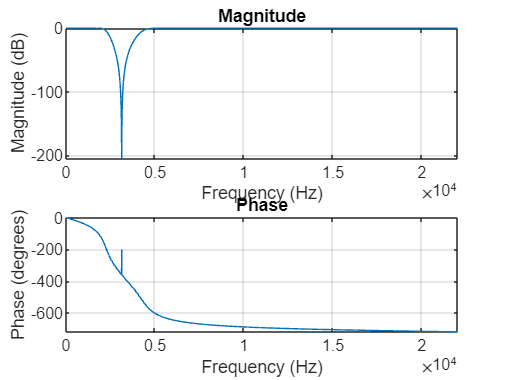

subplot(2,1,1)

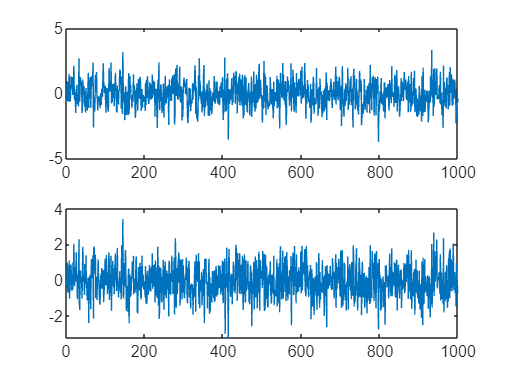

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
order=64

order = 64

fc=0.2

fc = 0.2000

b=fir1(order,fc,'low')

b =     0.0008    0.0005   -0.0000   -0.0006   -0.0012   -0.0015   -0.0011    0.0000    0.0017    0.0033    0.0039    0.0029   -0.0000   -0.0040   -0.0076   -0.0088   -0.0063    0.0000    0.0084    0.0157    0.0181    0.0129   -0.0000   -0.0173   -0.0327   -0.0387   -0.0288    0.0000    0.0451    0.0989    0.1500    0.1867    0.2000    0.1867    0.1500    0.0989    0.0451    0.0000   -0.0288   -0.0387   -0.0327   -0.0173   -0.0000    0.0129    0.0181    0.0157    0.0084    0.0000   -0.0063   -0.0088


freqz(b,1,2400,44100)
sgnl=randn(1,1000)

sgnl =    -0.6455   -0.2891    1.0004   -0.5881    1.5575   -1.3614    1.9001    0.1779   -2.1666    0.7069   -2.2253    0.3412    2.2512   -0.1661    0.4870    0.6730   -0.3750    0.8205   -0.3749    0.8785   -0.9980    0.0705   -0.2905   -0.7783    0.0886   -1.4737   -1.6398   -1.4533   -0.8034    0.8426    0.0498    1.2480    0.9871   -0.4811   -1.3608    0.0277   -0.3478    1.2241   -0.7336    1.5796    0.2543    0.4644   -0.7150   -1.0158   -0.1760    0.0213   -1.4609    0.1104   -0.7687    0.4214


filsgnl=filter(b,1,sgnl)

filsgnl =    -0.0005   -0.0005    0.0006    0.0005    0.0019    0.0004    0.0011   -0.0004   -0.0039   -0.0043   -0.0053   -0.0017    0.0055    0.0106    0.0134    0.0110    0.0012   -0.0119   -0.0255   -0.0307   -0.0245   -0.0030    0.0272    0.0549    0.0672    0.0512    0.0056   -0.0594   -0.1231   -0.1595   -0.1500   -0.0859    0.0199    0.1375    0.2302    0.2663    0.2275    0.1220   -0.0233   -0.1612   -0.2513   -0.2627   -0.1897   -0.0477    0.1309    0.3066    0.4432    0.5200    0.5240    0.4554


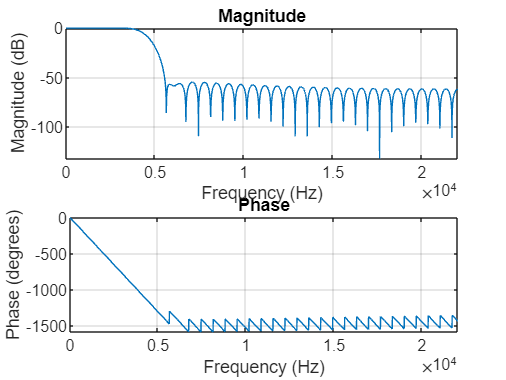

subplot(2,1,1)

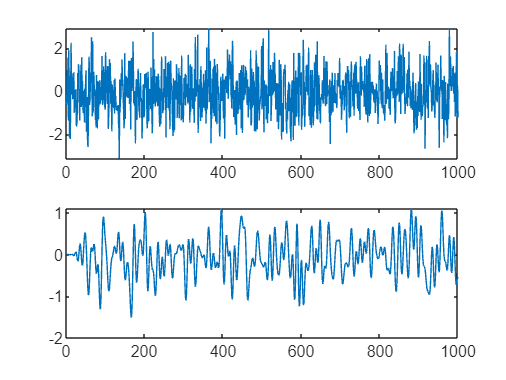

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
fc=0.2

fc = 0.2000

order=64

order = 64

b=fir1(order,fc,'high')

b =    -0.0008   -0.0005   -0.0000    0.0006    0.0012    0.0015    0.0011   -0.0000   -0.0017   -0.0033   -0.0039   -0.0029   -0.0000    0.0040    0.0076    0.0088    0.0063    0.0000   -0.0084   -0.0157   -0.0181   -0.0129   -0.0000    0.0173    0.0328    0.0388    0.0288    0.0000   -0.0452   -0.0990   -0.1502   -0.1868    0.8007   -0.1868   -0.1502   -0.0990   -0.0452    0.0000    0.0288    0.0388    0.0328    0.0173   -0.0000   -0.0129   -0.0181   -0.0157   -0.0084    0.0000    0.0063    0.0088


freqz(b,1,2400,44100)
sgnl=randn(1,1000)

sgnl =    -1.9184   -0.1311   -0.7686    2.3900    0.0772    0.3756    0.3956   -0.1125   -1.8290    2.0915    0.3591   -0.7943   -0.2273    1.5938    0.1552    0.1786   -0.3377   -1.5250   -0.7094   -0.8666    0.0715    0.1556   -0.1822    0.7310   -0.3476    0.2344   -0.8677   -0.9825   -0.2936    0.8245    0.1941    0.2977   -0.7101   -0.6877    0.5728    0.4452   -1.3260   -1.4999    1.0160   -0.0275   -0.1604    0.3788   -0.1072    0.2128    0.4681   -1.6161    0.0147   -0.0378    0.4038    0.3053


filsgnl=filter(b,1,sgnl)

filsgnl =     0.0015    0.0011    0.0006   -0.0027   -0.0037   -0.0039   -0.0023    0.0016    0.0077    0.0094    0.0090    0.0047   -0.0046   -0.0169   -0.0240   -0.0222   -0.0086    0.0148    0.0383    0.0517    0.0445    0.0140   -0.0329   -0.0811   -0.1074   -0.0938   -0.0309    0.0723    0.1906    0.2895    0.3381    0.3164   -1.6927   -0.0389   -0.8227    2.2196   -0.1621    0.1226    0.1628   -0.3162   -2.0212    1.8880    0.1230   -1.0537   -0.4684    1.4353    0.1365    0.3379   -0.0056   -1.0686


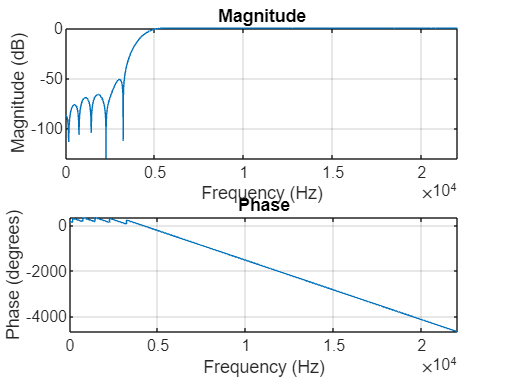

subplot(2,1,1)

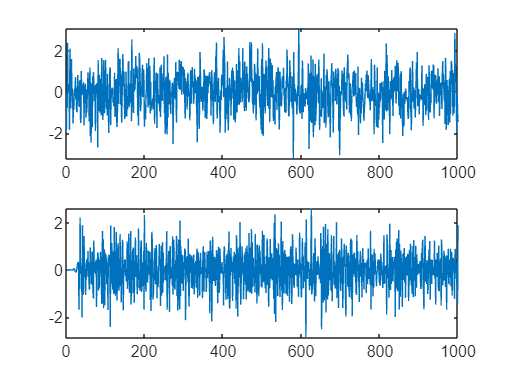

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
fl=0.2

fl = 0.2000

fh=0.4

fh = 0.4000

order=64

order = 64

b=fir1(order,[fl fh],'bandpass')

b =    -0.0003    0.0003   -0.0000   -0.0004    0.0005    0.0024    0.0030   -0.0000   -0.0044   -0.0053   -0.0015    0.0018   -0.0000   -0.0025    0.0029    0.0142    0.0165   -0.0000   -0.0220   -0.0253   -0.0069    0.0079   -0.0000   -0.0107    0.0125    0.0626    0.0752   -0.0000   -0.1180   -0.1598   -0.0572    0.1152    0.1997    0.1152   -0.0572   -0.1598   -0.1180   -0.0000    0.0752    0.0626    0.0125   -0.0107   -0.0000    0.0079   -0.0069   -0.0253   -0.0220   -0.0000    0.0165    0.0142


freqz(b,1,2400,44100)
sgnl=randn(1,1000)

sgnl =    -0.1386    0.4320    2.2530   -0.4596    0.0905    2.6081   -1.0372    0.2531   -0.2666    1.3175    0.1117    1.2714    0.4118    0.7579   -1.6723   -0.7335   -1.3232   -1.5116    0.9114    1.0439   -0.1370   -0.9904    1.0444    1.8247    0.7034   -0.8222   -0.4493    0.7032    0.0622    1.0264   -0.9819    1.5362   -0.2879   -0.7113   -1.1750    0.8558   -0.3362   -0.2742   -0.3773   -1.0397   -0.7084   -0.1192    2.1694   -0.3766    0.7987   -0.9420    0.8731    0.8960    0.7155    0.3716


filsgnl=filter(b,1,sgnl)

filsgnl =     0.0000   -0.0002   -0.0005    0.0009   -0.0004   -0.0018    0.0030    0.0061    0.0053   -0.0011   -0.0055   -0.0057   -0.0034   -0.0063   -0.0090   -0.0013    0.0210    0.0369    0.0228   -0.0125   -0.0373   -0.0348   -0.0232   -0.0235   -0.0229    0.0162    0.0977    0.1581    0.1123   -0.0545   -0.2393   -0.2980   -0.1575    0.1017    0.3127    0.3508    0.2196    0.0016   -0.2264   -0.4142   -0.4727   -0.2692    0.2115    0.7063    0.7803    0.2521   -0.5247   -0.8925   -0.5292    0.1985


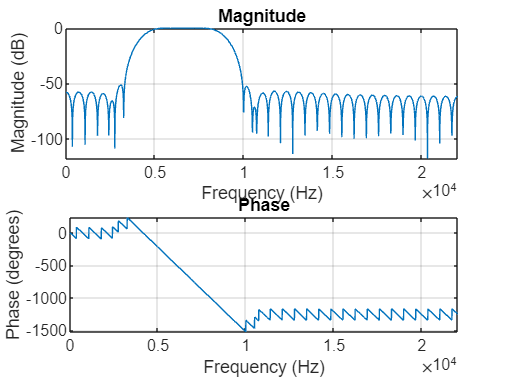

subplot(2,1,1)

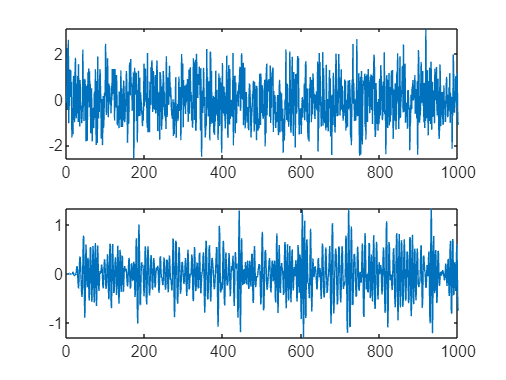

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)

clc
clear all
close all
fl=0.2

fl = 0.2000

fh=0.4

fh = 0.4000

order=64

order = 64

b=fir1(order,[fl fh],'stop')

b =     0.0003   -0.0003   -0.0000    0.0004   -0.0005   -0.0024   -0.0030    0.0000    0.0044    0.0053    0.0015   -0.0018   -0.0000    0.0025   -0.0029   -0.0143   -0.0166    0.0000    0.0221    0.0254    0.0069   -0.0080   -0.0000    0.0107   -0.0125   -0.0627   -0.0754    0.0000    0.1183    0.1602    0.0574   -0.1155    0.8010   -0.1155    0.0574    0.1602    0.1183    0.0000   -0.0754   -0.0627   -0.0125    0.0107   -0.0000   -0.0080    0.0069    0.0254    0.0221    0.0000   -0.0166   -0.0143


freqz(b,1,2400,44100)
sgnl=randn(1,1000)

sgnl =     1.1408    0.9331   -0.5206   -0.5897    1.3814   -0.3043    0.1954    1.1588    0.0330   -0.9552   -0.2731    1.1578   -0.7038    1.1412   -0.1581   -0.9685   -0.8927    0.9095    0.3323    0.2708   -1.4823    1.1944   -0.1312    0.4161    1.3425   -1.1639    0.4286   -1.3293   -1.9229    1.2900    0.0766    0.4311   -1.0052    0.3540   -0.7885    0.4838   -0.8637    0.3749    2.7224    0.8322   -0.4690   -0.2351   -1.5172    0.1093    1.0577    1.1568   -0.6355    0.3676    0.3064    0.0561


filsgnl=filter(b,1,sgnl)

filsgnl =     0.0003   -0.0001   -0.0004    0.0004    0.0004   -0.0039   -0.0055   -0.0004    0.0069    0.0084    0.0016   -0.0057   -0.0039    0.0062    0.0038   -0.0146   -0.0262   -0.0073    0.0280    0.0402    0.0113   -0.0208   -0.0156    0.0169    0.0118   -0.0573   -0.1087   -0.0396    0.1367    0.2470    0.1199   -0.1826    0.7686    0.7220   -0.3216   -0.1245    1.6612   -0.5273   -0.3467    0.8325    0.2773   -0.3515    0.0975    0.9244   -1.3062    0.7811    0.0584   -0.4536   -0.6602    0.6257


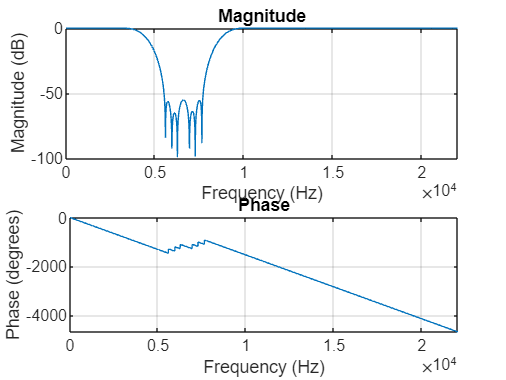

subplot(2,1,1)

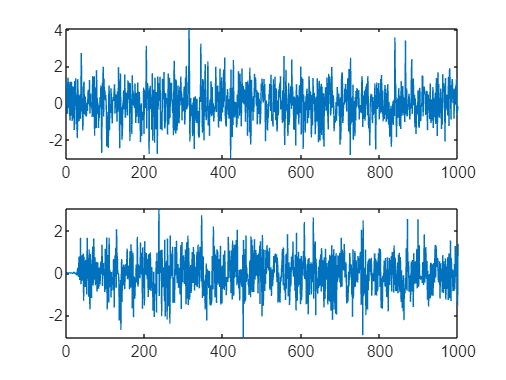

plot(sgnl)
subplot(2,1,2)
plot(filsgnl)